## Entrenamiento

load matlab_clasificacion\data_merit_1.mat

Se toma el convenio que:

- **Positivo: **patológico

- **Negativo: **normal 

VP = 0;
VN = 0;
FP = 0;
FN = 0;
for i = 1:length(C_clas)
    if C_clas(i) == C_real(i)
        switch C_clas(i)
            case 1
                VP = VP + 1;
            case 0
                VN = VN + 1;
        end
    else
        switch C_clas(i)
            case 1
                FP = FP + 1;
            case 0
                FN = FN + 1;
        end
    end
end
disp("La cantidad de verdaderos positivos es: "), disp(VP)

La cantidad de verdaderos positivos es: 
    69



disp("La cantidad de verdaderos negativos es: "), disp(VN)

La cantidad de verdaderos negativos es: 
    76



disp("La cantidad de falsos positivos es: "), disp(FP)

La cantidad de falsos positivos es: 
    26



disp("La cantidad de falsos positivos es: "), disp(FN)

La cantidad de falsos positivos es: 
    29



% Tasa de acierto
TA = (VP + VN) / (VP + FP + VN + FN);
disp("La tasa de acierto del clasificador es: "), disp(TA)

La tasa de acierto del clasificador es: 
    0.7250



% Sensibilidad
TPR = VP /(VP + FN);
disp("La sensibilidad del clasificador es: "), disp(TPR)

La sensibilidad del clasificador es: 
    0.7041



% Especificidad
TNR = VN /(VN + FP);
disp("La especificidad del clasificador es: "), disp(TNR)

La especificidad del clasificador es: 
    0.7451



load matlab_clasificacion\data_merit_2.mat

VP1 = 0;
VN1 = 0;
FP1 = 0;
FN1 = 0;
for i = 1:length(C_clas)
    if C_clas(i) == C_real(i)
        switch C_clas(i)
            case 1
                VP1 = VP1 + 1;
            case 0
                VN1 = VN1 + 1;
        end
    else
        switch C_clas(i)
            case 1
                FP1 = FP1 + 1;
            case 0
                FN1 = FN1 + 1;
        end
    end
end
disp("La cantidad de verdaderos positivos es: "), disp(VP)

La cantidad de verdaderos positivos es: 
    69



disp("La cantidad de verdaderos negativos es: "), disp(VN)

La cantidad de verdaderos negativos es: 
    76



disp("La cantidad de falsos positivos es: "), disp(FP)

La cantidad de falsos positivos es: 
    26



disp("La cantidad de falsos positivos es: "), disp(FN)

La cantidad de falsos positivos es: 
    29



% Tasa de acierto
TA1 = (VP1 + VN1) / (VP1 + FP1 + VN1 + FN1);
disp("La tasa de acierto del clasificador es: "), disp(TA1)

La tasa de acierto del clasificador es: 
    0.7250



% Sensibilidad
TPR1 = VP1 /(VP1 + FN1);
disp("La sensibilidad del clasificador es: "), disp(TPR1)

La sensibilidad del clasificador es: 
    0.8100



% Especificidad
TNR1 = VN1 /(VN1 + FP1);
disp("La especificidad del clasificador es: "), disp(TNR1)

La especificidad del clasificador es: 
    0.6400



- La tasa de acierto es la misma, sin embargo, difieren en la sensibilidad y la especificidad, dependiendo del coste de cada error se podrá decir que uno es mejor o peor.

FM = [VP FN; FP VN];
C = [0 90; 10 0];
CT_aux = FM .* C;
CT = (1/length(C_clas))*(CT_aux(1,2)+CT_aux(2,1));
disp(CT);

   14.3500



FM = [VP1 FN1; FP1 VN1];
C = [0 90; 10 0];
CT_aux = FM .* C;
CT = (1/length(C_clas))*(CT_aux(1,2)+CT_aux(2,1));
disp(CT);

   10.3500



- Como se puede observar, en términos de coste dará un mejor coste el segundo de los clasificadores pues el coste total será más bajo.

load matlab_clasificacion\data_merit_1.mat
C_matrix = confusionmat(C_real,C_clas);
disp(C_matrix)

    76    26
    29    69



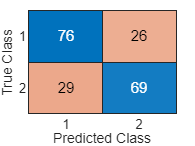

confusionchart(C_matrix)

- La tasa de acierto total, será el sumatorio de los valores de la diagonal entre los términos cruzados.

TA = sum((C_matrix(1,1)+C_matrix(2,2))/(C_matrix(1,1)+C_matrix(1,2)+C_matrix(2,1)+C_matrix(2,2)));
disp(TA)

- Analizando la matriz de confusión, la segunda clase presenta un mayor número de malas predicciones que la clase 1, por un número menor de aciertos.